# Multisensory integration

Duncan Tulimieri

October 21, 2020

NSCI643: Body and Space 

Prof. Jared Medina 

clear; clc;
cd('/Users/duncan/Dropbox/Classes/Fall 2020/NSCI643/Mutlisensory_integration')

## Ernst and Banks 2002

Estimate of environment property:


$$\hat{S_i } =f_i \left(S\right)$$


*S *: physical property being estimated

*f* : operation by which nervous system does the estimation

Maximum likelihood estimate:


$$\hat{S} =\sum_i w_i \hat{S_i } \;\textrm{with}\;w_i =\frac{1/{\sigma_i }^2 }{\sum_j 1/{\sigma_j }^2 }$$



$$\sigma^2 =\textrm{varaince}\;$$


Variance of final (visual-haptic) estimate:


$${\sigma_{\textrm{VH}} }^2 =\frac{{\sigma_V }^2 {\sigma_H }^2 }{{\sigma_V }^2 +{\sigma_H }^2 }$$


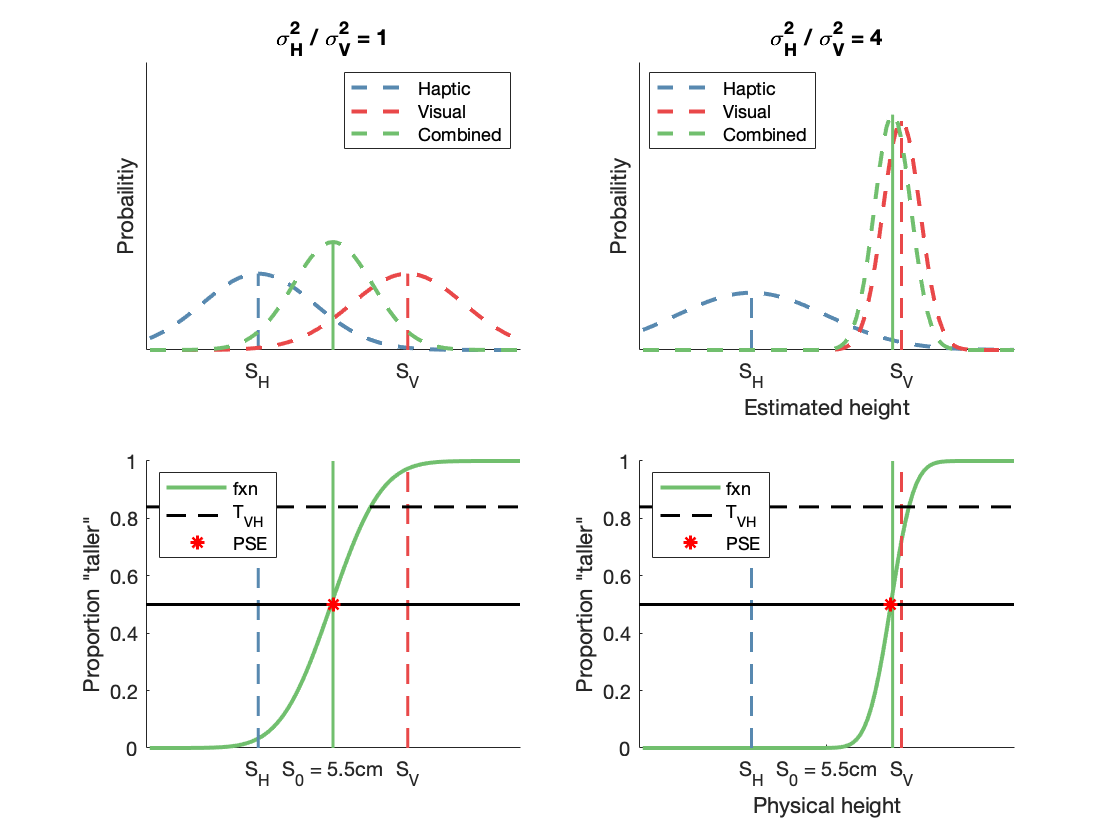

% Figure 1 example 
% a. 
% set initical conditions 
F1.x = 1:100; 
F1.Adata.mu_haptic = 30;
F1.Adata.sigma_haptic = 15; 
F1.Adata.mu_visual = 70;
F1.Adata.sigma_visual = 15;
% create normal distributions 
F1.Adata.haptic = normpdf(F1.x, F1.Adata.mu_haptic, F1.Adata.sigma_haptic);
F1.Adata.visual = normpdf(F1.x, F1.Adata.mu_visual, F1.Adata.sigma_visual); 
% plot 
figure;
subplot(2,2,1);
cc = linspecer(3); % create nice rgb triplets 
F1.H = plot(F1.Adata.haptic, '--', 'linewidth', 2, 'color', cc(1,:));
hold on 
plot([F1.Adata.mu_haptic F1.Adata.mu_haptic], [0 max(F1.Adata.haptic)], '--', 'color', cc(1,:), 'linewidth', 1.5);
F1.V = plot(F1.Adata.visual, '--', 'linewidth', 2, 'color', cc(2,:));
plot([F1.Adata.mu_visual F1.Adata.mu_visual], [0 max(F1.Adata.visual)], '--', 'color', cc(2,:), 'linewidth', 1.5);
% Use pointwise multiplication to sum (for ease) 
F1.Adata.haptic_visual = (F1.Adata.haptic .* F1.Adata.visual)/sum(F1.Adata.haptic .* F1.Adata.visual);
F1.Adata.mu_hv = dot(1:100,F1.Adata.haptic_visual); 
F1.HV = plot(F1.Adata.haptic_visual, '--', 'linewidth', 2, 'color', cc(3,:));
plot([F1.Adata.mu_hv F1.Adata.mu_hv], [0 max(F1.Adata.haptic_visual)], '-', 'color', cc(3,:), 'linewidth', 1.5);
F1.g= gca; 
F1.g.YLim(2) = 0.1; 
F1.g.YTick = []; F1.g.YTickLabel = [];
F1.g.XTick = [F1.Adata.mu_haptic F1.Adata.mu_visual]; F1.g.XTickLabel = {'S_H', 'S_V'};
legend([F1.H F1.V F1.HV], {'Haptic', 'Visual', 'Combined'}, 'location', 'best')
ylabel('Probailitiy')
box off 
title(append('\sigma_H^2 / \sigma_V^2 = ', sprintf('%d', F1.Adata.sigma_haptic / F1.Adata.sigma_visual)))

% b. 
subplot(2,2,2); 
% set initial conditions 
F1.Bdata.mu_haptic = 30;
F1.Bdata.sigma_haptic = 5*4; 
F1.Bdata.mu_visual = 70;
F1.Bdata.sigma_visual = 5;
% create normal distributions 
F1.Bdata.haptic = normpdf(F1.x, F1.Bdata.mu_haptic, F1.Bdata.sigma_haptic);
F1.Bdata.visual = normpdf(F1.x, F1.Bdata.mu_visual, F1.Bdata.sigma_visual); 
% plot 
F1.H = plot(F1.Bdata.haptic, '--', 'linewidth', 2, 'color', cc(1,:));
hold on 
plot([F1.Bdata.mu_haptic F1.Bdata.mu_haptic], [0 max(F1.Bdata.haptic)], '--', 'color', cc(1,:), 'linewidth', 1.5);
V = plot(F1.Bdata.visual, '--', 'linewidth', 2, 'color', cc(2,:));
plot([F1.Bdata.mu_visual F1.Bdata.mu_visual], [0 max(F1.Bdata.visual)], '--', 'color', cc(2,:), 'linewidth', 1.5);
% Use pointwise multiplication to sum (for ease) 
F1.Bdata.haptic_visual = (F1.Bdata.haptic .* F1.Bdata.visual)/sum(F1.Bdata.haptic .* F1.Bdata.visual);
F1.Bdata.mu_hv = dot(1:100,F1.Bdata.haptic_visual); 
F1.HV = plot(F1.Bdata.haptic_visual, 'k--', 'linewidth', 2, 'color', cc(3,:));
plot([F1.Bdata.mu_hv F1.Bdata.mu_hv], [0 max(F1.Bdata.haptic_visual)], '-', 'color', cc(3,:), 'linewidth', 1.5);
F1.g= gca; 
F1.g.YLim(2) = 0.1; 
F1.g.YTick = []; F1.g.YTickLabel = [];
F1.g.XTick = [F1.Bdata.mu_haptic F1.Bdata.mu_visual]; F1.g.XTickLabel = {'S_H', 'S_V'};
legend([F1.H F1.V F1.HV], {'Haptic', 'Visual', 'Combined'}, 'location', 'best')
ylabel('Probailitiy')
xlabel('Estimated height')
box off 
title(append('\sigma_H^2 / \sigma_V^2 = ', sprintf('%d', F1.Bdata.sigma_haptic / F1.Bdata.sigma_visual)))

% c. 
subplot(2,2,3); 
% calculate cdf (i.e. the integral)
F1.Adata.psychometric = cumsum(F1.Adata.haptic_visual);
% plot 
F1.AP = plot(F1.Adata.psychometric, '-', 'linewidth', 2, 'color', cc(3,:));
hold on 
F1.g=gca;
ylabel('Proportion "taller"'); 
F1.g.XTick = [F1.Adata.mu_haptic F1.Adata.mu_hv F1.Adata.mu_visual]; F1.g.XTickLabel = {'S_H','S_0 = 5.5cm', 'S_V'};
plot([F1.Adata.mu_haptic F1.Adata.mu_haptic], [0 1], '--', 'color', cc(1,:), 'linewidth', 1.5);
plot([F1.Adata.mu_visual F1.Adata.mu_visual], [0 1], '--', 'color', cc(2,:), 'linewidth', 1.5);
plot([F1.Adata.mu_hv F1.Adata.mu_hv], [0 1], '-', 'color', cc(3,:), 'linewidth', 1.5);
F1.TVH = hline(0.84, 'k', '--', 1.5); % T_VH
hline(0.5, 'k', '-', 1.5); 
F1.PSE = plot(argmin(abs(F1.Adata.psychometric-0.5)), 0.5, 'r*', 'linewidth', 1.5); % PSE 
legend([F1.AP F1.TVH F1.PSE], {'fxn', 'T_V_H', 'PSE'}, 'location', 'northwest')
box off 

% d. 
subplot(2,2,4); 
% calculate cdf (i.e. the integral) 
F1.Bdata.psychometric = cumsum(F1.Bdata.haptic_visual);
% plot
F1.BP = plot(F1.Bdata.psychometric, '-', 'linewidth', 2, 'color', cc(3,:));
hold on 
F1.g=gca;
ylabel('Proportion "taller"'); 
F1.g.XTick = [F1.Bdata.mu_haptic F1.Adata.mu_hv F1.Bdata.mu_visual]; F1.g.XTickLabel = {'S_H','S_0 = 5.5cm', 'S_V'};
plot([F1.Bdata.mu_haptic F1.Bdata.mu_haptic], [0 1], '--', 'color', cc(1,:), 'linewidth', 1.5);
plot([F1.Bdata.mu_visual F1.Bdata.mu_visual], [0 1], '--', 'color', cc(2,:), 'linewidth', 1.5);
plot([F1.Bdata.mu_hv F1.Bdata.mu_hv], [0 1], '-', 'color', cc(3,:), 'linewidth', 1.5);
F1.TVH = hline(0.84, 'k', '--', 1.5); % T_VH
hline(0.5, 'k', '-', 1.5); 
F1.PSE = plot(argmin(abs(F1.Bdata.psychometric-0.5)), 0.5, 'r*', 'linewidth', 1.5); % PSE 
legend([F1.BP F1.TVH F1.PSE], {'fxn', 'T_V_H', 'PSE'}, 'location', 'northwest')
box off 
xlabel('Physical height')

Relationship between weights, variance, and thresholds


$$\frac{w_V }{w_H }=\frac{{\sigma_H }^2 }{{\sigma_V }^2 }=\frac{{T_H }^2 }{{T_V }^2 }$$


T_H & T_V : haptic and visual thresholds (84%) 

% Figure 3 
figure;

% a
% visually estimate data 
F2.Ax = [47, 50.5, 53, 53.5, 54.5, 55.5, 57.5, 57, 60, 63];
F2.AHaptic.data = [0.1, 0.14, 0.3, 0.32, 0.47, 0.53, 0.67, 0.82, 0.83, 0.93]; 
F2.AVisual.data.p0 = [0.001, 0.05, 0.1, 0.24, 0.5, 0.69, 0.74, 0.9, 0.97, 1];
F2.AVisual.data.p67 = [0.001, 0.05, 0.19, 0.22, 0.4, 0.64, 0.82, 0.9, 0.97, 1];
F2.AVisual.data.p133 = [0.1, 0.23, 0.34, 0.25, 0.5, 0.53, 0.54, 0.82, 0.97, 1];
F2.Axp200 = [47, 50.5, 53, 54.5, 55.5, 57.5, 60, 63]; % deal with missing data 
F2.AVisual.data.p200 = [0.26, 0.28, 0.4, 0.38, 0.52, 0.53 0.73, 0.74];

% fit psychometric functions 

Fit prbability data to the logistic sigmoid equation: $f\left(x\right)=\frac{a}{1+\exp \left(-b*\left(x-c\right)\right)}$ where a = curves maximum value (i.e. 1), b = logistic growth rate (i.e. steepness of function), and c = sigmoid's midpoint. 

In this function, variables b and c are free parameters and a is always 1. 

fun = @(x,xdata) (1 ./ (1 + exp(-x(1)*(xdata - x(2)))));  % define function 
x0 = [0.5, 55]; % initial guesses (logistic growth rate of 0.5 and sigmoid midpoint at 55)
% use nonlinear least squares fit 
F2.AHaptic.coeffs = lsqcurvefit(fun, x0, F2.Ax, F2.AHaptic.data); 


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


F2.AVisual.coeffs.p0 = lsqcurvefit(fun, x0, F2.Ax, F2.AVisual.data.p0);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


F2.AVisual.coeffs.p67 = lsqcurvefit(fun, x0, F2.Ax, F2.AVisual.data.p67);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


F2.AVisual.coeffs.p133 = lsqcurvefit(fun, x0, F2.Ax, F2.AVisual.data.p133);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


F2.AVisual.coeffs.p200 = lsqcurvefit(fun, x0, F2.Axp200, F2.AVisual.data.p200);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


F2.Afitcurve = linspace(F2.Ax(1), F2.Ax(length(F2.Ax)));
F2.Ap200fitcurve = linspace(F2.Axp200(1), F2.Axp200(length(F2.Axp200)));

% plot 
subplot(2,2,1); 
F2.AH = plot(F2.Ax, F2.AHaptic.data, 'rx'); 
hold on 
plot(F2.Afitcurve, fun(F2.AHaptic.coeffs, F2.Afitcurve), 'r--')
F2.AV0 = plot(F2.Ax, F2.AVisual.data.p0, 'bo');
plot(F2.Afitcurve, fun(F2.AVisual.coeffs.p0, F2.Afitcurve), 'b-')
F2.AV67 = plot(F2.Ax, F2.AVisual.data.p67, 'square', 'color', 'b');
plot(F2.Afitcurve, fun(F2.AVisual.coeffs.p67, F2.Afitcurve), 'b-')
F2.AV133 = plot(F2.Ax, F2.AVisual.data.p133, 'diamond', 'color', 'b');
plot(F2.Afitcurve, fun(F2.AVisual.coeffs.p133, F2.Afitcurve), 'b-')
F2.AV200 = plot(F2.Axp200, F2.AVisual.data.p200, 'b^');
plot(F2.Ap200fitcurve, fun(F2.AVisual.coeffs.p200, F2.Ap200fitcurve), 'b-')
g = gca;
g.XTick = [50 55 60]; 
hline(0.5, 'k', '-', 1); % 50% proportion
vline(55, 'k', '-', 1); % standard 
hline(0.84, 'k', '--', 1); % T_VH
legend([F2.AH F2.AV0, F2.AV67, F2.AV133, F2.AV200],{'Haptic', 'V0%', 'V67%', 'V133%', 'V200%'}, 'location', 'northwest')
xlabel('Comparison height (mm)'); ylabel('Proportion of trials perceived as ''taller''')
title('Within-modality discrimination')

% b. 
subplot(2,2,2);
% visually estimate data 
F2.Bx = linspace(45, 65, 10); % only do 10 data points because I don't have enough time to go through and get all 
F2.BVisual.data.p0 = [0, 0, 0, 0, 0.1, 0.15, 0.4, 0.76, 0.98, 1];
F2.BVisual.data.p67 = [0, 0, 0, 0, 0.13, 0.19, 0.41, 0.74, 0.96, 1];
F2.BVisual.data.p133 = [0, 0.01, 0.08, 0.09, 0.24, 0.47, 0.67, 0.82, 0.96, 1];
F2.BVisual.data.p200 = [0, 0.1, 0.18, 0.26, 0.42, 0.63, 0.76, 0.82, 0.96, 1];

% fit psychometric functions 
F2.BVisual.coeffs.p0 = lsqcurvefit(fun, x0, F2.Bx, F2.BVisual.data.p0);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


F2.BVisual.coeffs.p67 = lsqcurvefit(fun, x0, F2.Bx, F2.BVisual.data.p67);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


F2.BVisual.coeffs.p133 = lsqcurvefit(fun, x0, F2.Bx, F2.BVisual.data.p133);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


F2.BVisual.coeffs.p200 = lsqcurvefit(fun, x0, F2.Bx, F2.BVisual.data.p200);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


F2.Bfitcurve = linspace(F2.Bx(1), F2.Bx(length(F2.Bx)));

% plot 
purp = rgb_triplet('purple');
F2.BV0 = plot(F2.Bx, F2.BVisual.data.p0, 'o', 'color', purp, 'markerfacecolor', purp);
hold on 
plot(F2.Bfitcurve, fun(F2.BVisual.coeffs.p0, F2.Bfitcurve), '-', 'color', purp)
F2.BV67 = plot(F2.Bx, F2.BVisual.data.p67, 'o', 'color', purp, 'markerfacecolor', purp);
plot(F2.Bfitcurve, fun(F2.BVisual.coeffs.p67, F2.Bfitcurve), '-', 'color', purp)
F2.BV133 = plot(F2.Bx, F2.BVisual.data.p133, 'o', 'color', purp, 'markerfacecolor', purp);
plot(F2.Bfitcurve, fun(F2.BVisual.coeffs.p133, F2.Bfitcurve), '-', 'color', purp)
F2.BV200 = plot(F2.Bx, F2.BVisual.data.p200, 'o', 'color', purp, 'markerfacecolor', purp);
plot(F2.Bfitcurve, fun(F2.BVisual.coeffs.p200, F2.Bfitcurve), '-', 'color', purp)
g = gca; 
g.XTickLabel = {'45', 'S_H', '55', 'S_V', '65'};
ylabel('Proportion of trials perceived as ''taller'''); xlabel('Normalized comparison height (mm)')
title(sprintf('Visual-haptic discrimination\n (normalized across \\Delta)'))
hline(0.5, 'k', '-', 1); hline(0.84, 'k', '--', 1);
vline(50, 'k', '--', 1); vline(60, 'k', '--', 1);
legend([F2.BV0 F2.BV67 F2.BV133 F2.BV200], {'VH0%', 'VH67%', 'VH133%', 'VH200%'}, 'location', 'northwest')

% c. (would get better results/figure if actually had all data) 
% predicted: use equation 5 with data from a. 

Normailzed weights for optimal integration (sum to 1): 


$$w_v =\frac{{T_H }^2 }{{T_v }^2 +{T_H }^2 }\;\textrm{and}\;w_H =\frac{{T_V }^2 }{{T_v }^2 +{T_H }^2 }$$


Experimentally derived weights:


$$w_v =\left(\textrm{PSE}-S_H \right)/\left(S_V -S_H \right)$$


PSE : point of subjective equality (i.e. height of comparison stimulus that matched the apparent height of the standard stimulus) 

% find where functions cross T_V_H
F2.CTH = F2.Afitcurve(find(fun(F2.AHaptic.coeffs, F2.Afitcurve) >= 0.84, 1, 'first'));
F2.CTV0 = F2.Afitcurve(find(fun(F2.AVisual.coeffs.p0, F2.Afitcurve) >= 0.84, 1, 'first'));
F2.CTV67 = F2.Afitcurve(find(fun(F2.AVisual.coeffs.p67, F2.Afitcurve) >= 0.84, 1, 'first'));
F2.CTV133 = F2.Afitcurve(find(fun(F2.AVisual.coeffs.p133, F2.Afitcurve) >= 0.84, 1, 'first'));
% TV200 = F2.Afitcurve(find(fun(F2.AVisual.coeffs.p200, F2.Afitcurve) >=
% 0.84, 1, 'first')); % curve fit never hit 0.84
F2.CTV200 = 61; 
% calculate normalized weights for optimal integration 
F2.CPredicted.WV.V0 = F2.CTH^2 / (F2.CTV0^2 + F2.CTH^2); F2.CPredicted.WH.V0 = F2.CTV0^2 / (F2.CTV0^2 + F2.CTH^2);
F2.CPredicted.WV.V67 = F2.CTH^2 / (F2.CTV67^2 + F2.CTH^2); F2.CPredicted.WH.V67 = F2.CTV67^2 / (F2.CTV67^2 + F2.CTH^2);
F2.CPredicted.WV.V133 = F2.CTH^2 / (F2.CTV133^2 + F2.CTH^2); F2.CPredicted.WH.V133 = F2.CTV133^2 / (F2.CTV133^2 + F2.CTH^2);
F2.CPredicted.WV.V200 = F2.CTH^2 / (F2.CTV200^2 + F2.CTH^2); 
F2.CPredicted.WH.V200 = F2.CTV200^2 / (F2.CTV200^2 + F2.CTH^2);
% calculate experimentally derived weights 
F2.CSH = 50; F2.CSV = 60; 
F2.CE0 = (F2.Bfitcurve(find(fun(F2.BVisual.coeffs.p0, F2.Bfitcurve) >= 0.5, 1, 'first')) - F2.CSH) / (F2.CSV - F2.CSH); 
F2.CE67 = (F2.Bfitcurve(find(fun(F2.BVisual.coeffs.p67, F2.Bfitcurve) >= 0.5, 1, 'first')) - F2.CSH) / (F2.CSV - F2.CSH); 
F2.CE133 = (F2.Bfitcurve(find(fun(F2.BVisual.coeffs.p133, F2.Bfitcurve) >= 0.5, 1, 'first')) - F2.CSH) / (F2.CSV - F2.CSH); 
F2.CE200 = (F2.Bfitcurve(find(fun(F2.BVisual.coeffs.p200, F2.Bfitcurve) >= 0.5, 1, 'first')) - F2.CSH) / (F2.CSV - F2.CSH); 
% plot 
subplot(2,2,3);
noiselvl = [0, 67, 133, 200];
F2.CVWALL = [F2.CPredicted.WV.V0 F2.CPredicted.WV.V67 F2.CPredicted.WV.V133 F2.CPredicted.WV.V200];
F2.CVW = plot(noiselvl, F2.CVWALL, 'k-'); % visual weight 
hold on 
F2.CEplt = plot(noiselvl(1), F2.CE0, 'o', 'color', purp, 'markerfacecolor', purp);
plot(noiselvl(2), F2.CE67, 's', 'color', purp, 'markerfacecolor', purp);
plot(noiselvl(3), F2.CE133, 'd', 'color', purp, 'markerfacecolor', purp);
plot(noiselvl(4), F2.CE200, '^', 'color', purp, 'markerfacecolor', purp);

yyaxis right 
g = gca; g.YDir = 'reverse';
g.YColor = 'b'; 
F2.CHWALL = [F2.CPredicted.WH.V0 F2.CPredicted.WH.V67 F2.CPredicted.WH.V133 F2.CPredicted.WH.V200]; 
F2.CHW = plot(noiselvl, F2.CHWALL, 'b-'); % haptic weight 
ylabel('Haptic weight'); 

yyaxis left 
ylabel('Visual weight');
g.XTick = [0 67 133 200];
legend([F2.CVW F2.CHW F2.CEplt], {'V predicted', 'H predicted', 'Empirical'}, 'location', 'southwest')
title('Weights (PSEs)'); xlabel('Noise levle (%)')

% d. (need subject data for proper graphing) 
subplot(2,2,4);
% empirical visual-haptic discrimination thresholds 
F2.DStandard = 55; 
F2.DETH = abs(F2.DStandard - F2.Afitcurve(find(fun(F2.AHaptic.coeffs, F2.Afitcurve) >= 0.5, 1, 'first')));
F2.DETV0 = abs(F2.DStandard - F2.Afitcurve(find(fun(F2.AVisual.coeffs.p0, F2.Afitcurve) >= 0.5, 1, 'first')));
F2.DETV67 = abs(F2.DStandard - F2.Afitcurve(find(fun(F2.AVisual.coeffs.p67, F2.Afitcurve) >= 0.5, 1, 'first')));
F2.DETV133 = abs(F2.DStandard - F2.Afitcurve(find(fun(F2.AVisual.coeffs.p133, F2.Afitcurve) >= 0.5, 1, 'first')));
% F2.DETV200 = abs(F2.DStandard - F2.Afitcurve(find(fun(F2.AVisual.coeffs.p200, F2.Afitcurve) >= 0.5, 1, 'first'))); % value to large 
F2.DETV200 = 0.2; 

Predict visual-haptic discrimination thresholds:


$${T_{\textrm{VH}} }^2 =\frac{{T_V }^2 {T_H }^2 }{{T_V }^2 +{T_H }^2 }\longleftrightarrow \frac{1}{{T_{\textrm{VH}} }^2 }=\frac{1}{{T_V }^2 }+\frac{1}{{T_H }^2 }$$


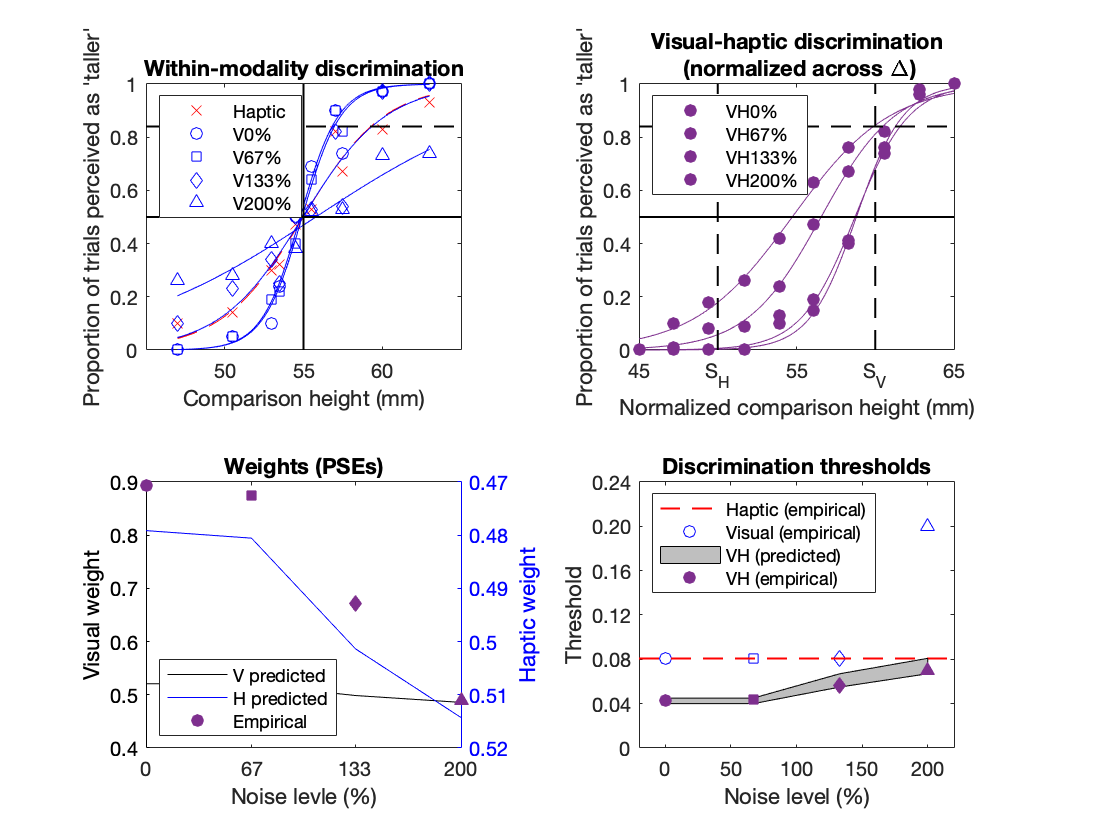

% predicted visual-haptic discrimination threholds 
F2.DP0 = (F2.DETV0^2*F2.DETH^2)/(F2.DETV0^2+F2.DETH^2);
F2.DP67 = (F2.DETV67^2*F2.DETH^2)/(F2.DETV67^2+F2.DETH^2);
F2.DP133 = (F2.DETV133^2*F2.DETH^2)/(F2.DETV133^2+F2.DETH^2);
F2.DP200 = (F2.DETV200^2*F2.DETH^2)/(F2.DETV200^2+F2.DETH^2);

F2.DVE = plot(noiselvl(1), F2.DETV0, 'o', 'color', 'b');
hold on 
plot(noiselvl(2), F2.DETV67, 's', 'color', 'b')
plot(noiselvl(3), F2.DETV133, 'd', 'color', 'b')
plot(noiselvl(4), F2.DETV200, '^', 'color', 'b')
xlim([-20 220])
F2.DH = hline(F2.DETH, 'r', '--', 1); 
% hardcode the remaining information due to lack of subject data for proper
% plotting 
plot(noiselvl, [0.045 0.045 0.067 0.0809], 'k-')
plot(noiselvl, [0.04 0.04 0.055 0.067], 'k-')
F2.VHP = patch([noiselvl fliplr(noiselvl)], [[0.045 0.045 0.067 0.0809] fliplr([0.04 0.04 0.055 0.067])], [.75 .75 .75]);
F2.VHE = plot(noiselvl(1), 0.043, 'o', 'color', purp, 'markerfacecolor', purp);
plot(noiselvl(2), 0.044, 's', 'color', purp, 'markerfacecolor', purp)
plot(noiselvl(3), 0.056, 'd', 'color', purp, 'markerfacecolor', purp)
plot(noiselvl(4), 0.07, '^', 'color', purp, 'markerfacecolor', purp)
g = gca; ylim([0 0.24]); g.YTick = 0:0.04:0.24; 
g.YTickLabel = {'0', '0.04', '0.08', '0.12', '0.16', '0.20', '0.24'};
xlabel('Noise level (%)'); ylabel('Threshold'); title('Discrimination thresholds')
legend([F2.DH F2.DVE F2.VHP F2.VHE], {'Haptic (empirical)', 'Visual (empirical)', 'VH (predicted)', 'VH (empirical)'}, 'location', 'northwest')

function idx = argmin(x)
% INPUT:
% x: input vector 

% OUTPUT:
% idx: index of smallest value in x

[~,idx] = min(x);

end

function handle = hline(y, color, linestyle, linewidth)
% INPUT:
% y: y-value for line 
% color: rgb triplet for line 
% linestyle: linestyle 
% linewidth: linewidth

% OUTPUT:
% handle: line handle 

% Get current axes 
g = gca; 

% Plot on current figure 
handle = plot([g.XLim(1) g.XLim(2)], [y y], 'color', color, 'linestyle', linestyle, 'linewidth', linewidth);

end

function [RGB] = rgb_triplet(color_string)
% INPUT:
% color_str: string defining color 
% color_str options: 'blue', 'oragne', 'yellow', 'purple', 'green', 'cyan',
% 'maroon'

% OUTPUT:
% RGB: rgb triplet according to string 

options = {'blue', 'orange', 'yellow', 'purple', 'green', 'cyan', 'maroon'};
triplets = [0 0.4470 0.7410; ...
    0.8500 0.3250 0.0980; ...
    0.9290 0.6940 0.1250; ...
    0.4940 0.1840 0.5560; ...
    0.4660 0.6740 0.1880; ...
    0.3010 0.7450 0.9330; ...
    0.6350 0.0780 0.1840];

idx = strmatch(color_string, options);
if isempty(idx)
    sprintf('Viable options:\nblue\norange\nyellow\npurple\ngreen\ncyan\nmaroon')
end

RGB = triplets(idx,:); 

end

function handle = vline(x, color, linestyle, linewidth)
% INPUTS:
% x: x-value for line 
% color: rgb triplet for lines color
% linestyle: linestyle 
% linewidth: linewdith

% OUTPUT:
% handle: line handle

% Get current axes
g = gca;

% Plot line 
handle = plot([x x], [g.YLim(1) g.YLim(2)], 'color', color, 'linestyle', linestyle,'linewidth', linewidth);

end

% function lineStyles = linspecer(N)
% This function creates an Nx3 array of N [R B G] colors
% These can be used to plot lots of lines with distinguishable and nice
% looking colors.
% 
% lineStyles = linspecer(N);  makes N colors for you to use: lineStyles(ii,:)
% 
% colormap(linspecer); set your colormap to have easily distinguishable 
%                      colors and a pleasing aesthetic
% 
% lineStyles = linspecer(N,'qualitative'); forces the colors to all be distinguishable (up to 12)
% lineStyles = linspecer(N,'sequential'); forces the colors to vary along a spectrum 
% 
% % Examples demonstrating the colors.
% 
% LINE COLORS
% N=6;
% X = linspace(0,pi*3,1000); 
% Y = bsxfun(@(x,n)sin(x+2*n*pi/N), X.', 1:N); 
% C = linspecer(N);
% axes('NextPlot','replacechildren', 'ColorOrder',C);
% plot(X,Y,'linewidth',5)
% ylim([-1.1 1.1]);
% 
% SIMPLER LINE COLOR EXAMPLE
% N = 6; X = linspace(0,pi*3,1000);
% C = linspecer(N)
% hold off;
% for ii=1:N
%     Y = sin(X+2*ii*pi/N);
%     plot(X,Y,'color',C(ii,:),'linewidth',3);
%     hold on;
% end
% 
% COLORMAP EXAMPLE
% A = rand(15);
% figure; imagesc(A); % default colormap
% figure; imagesc(A); colormap(linspecer); % linspecer colormap
% 
%   See also NDHIST, NHIST, PLOT, COLORMAP, 43700-cubehelix-colormaps
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% by Jonathan Lansey, March 2009-2013 � Lansey at gmail.com               %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
%% credits and where the function came from
% The colors are largely taken from:
% http://colorbrewer2.org and Cynthia Brewer, Mark Harrower and The Pennsylvania State University
% 
% 
% She studied this from a phsychometric perspective and crafted the colors
% beautifully.
% 
% I made choices from the many there to decide the nicest once for plotting
% lines in Matlab. I also made a small change to one of the colors I
% thought was a bit too bright. In addition some interpolation is going on
% for the sequential line styles.
% 
% 
%%

function lineStyles=linspecer(N,varargin)

if nargin==0 % return a colormap
    lineStyles = linspecer(128);
    return;
end

if ischar(N)
    lineStyles = linspecer(128,N);
    return;
end

if N<=0 % its empty, nothing else to do here
    lineStyles=[];
    return;
end

% interperet varagin
qualFlag = 0;
colorblindFlag = 0;

if ~isempty(varargin)>0 % you set a parameter?
    switch lower(varargin{1})
        case {'qualitative','qua'}
            if N>12 % go home, you just can't get this.
                warning('qualitiative is not possible for greater than 12 items, please reconsider');
            else
                if N>9
                    warning(['Default may be nicer for ' num2str(N) ' for clearer colors use: whitebg(''black''); ']);
                end
            end
            qualFlag = 1;
        case {'sequential','seq'}
            lineStyles = colorm(N);
            return;
        case {'white','whitefade'}
            lineStyles = whiteFade(N);return;
        case 'red'
            lineStyles = whiteFade(N,'red');return;
        case 'blue'
            lineStyles = whiteFade(N,'blue');return;
        case 'green'
            lineStyles = whiteFade(N,'green');return;
        case {'gray','grey'}
            lineStyles = whiteFade(N,'gray');return;
        case {'colorblind'}
            colorblindFlag = 1;
        otherwise
            warning(['parameter ''' varargin{1} ''' not recognized']);
    end
end      
% *.95
% predefine some colormaps
  set3 = colorBrew2mat({[141, 211, 199];[ 255, 237, 111];[ 190, 186, 218];[ 251, 128, 114];[ 128, 177, 211];[ 253, 180, 98];[ 179, 222, 105];[ 188, 128, 189];[ 217, 217, 217];[ 204, 235, 197];[ 252, 205, 229];[ 255, 255, 179]}');
set1JL = brighten(colorBrew2mat({[228, 26, 28];[ 55, 126, 184]; [ 77, 175, 74];[ 255, 127, 0];[ 255, 237, 111]*.85;[ 166, 86, 40];[ 247, 129, 191];[ 153, 153, 153];[ 152, 78, 163]}'));
set1 = brighten(colorBrew2mat({[ 55, 126, 184]*.85;[228, 26, 28];[ 77, 175, 74];[ 255, 127, 0];[ 152, 78, 163]}),.8);

% colorblindSet = {[215,25,28];[253,174,97];[171,217,233];[44,123,182]};
colorblindSet = {[215,25,28];[253,174,97];[171,217,233]*.8;[44,123,182]*.8};

set3 = dim(set3,.93);

if colorblindFlag
    switch N
        %     sorry about this line folks. kind of legacy here because I used to
        %     use individual 1x3 cells instead of nx3 arrays
        case 4
            lineStyles = colorBrew2mat(colorblindSet);
        otherwise
            colorblindFlag = false;
            warning('sorry unsupported colorblind set for this number, using regular types');
    end
end
if ~colorblindFlag
    switch N
        case 1
            lineStyles = { [  55, 126, 184]/255};
        case {2, 3, 4, 5 }
            lineStyles = set1(1:N);
        case {6 , 7, 8, 9}
            lineStyles = set1JL(1:N)';
        case {10, 11, 12}
            if qualFlag % force qualitative graphs
                lineStyles = set3(1:N)';
            else % 10 is a good number to start with the sequential ones.
                lineStyles = cmap2linspecer(colorm(N));
            end
        otherwise % any old case where I need a quick job done.
            lineStyles = cmap2linspecer(colorm(N));
    end
end
lineStyles = cell2mat(lineStyles);

end

% extra functions
function varIn = colorBrew2mat(varIn)
for ii=1:length(varIn) % just divide by 255
    varIn{ii}=varIn{ii}/255;
end        
end

function varIn = brighten(varIn,varargin) % increase the brightness

if isempty(varargin),
    frac = .9; 
else
    frac = varargin{1}; 
end

for ii=1:length(varIn)
    varIn{ii}=varIn{ii}*frac+(1-frac);
end        
end

function varIn = dim(varIn,f)
    for ii=1:length(varIn)
        varIn{ii} = f*varIn{ii};
    end
end

function vOut = cmap2linspecer(vIn) % changes the format from a double array to a cell array with the right format
vOut = cell(size(vIn,1),1);
for ii=1:size(vIn,1)
    vOut{ii} = vIn(ii,:);
end
end
%%
% colorm returns a colormap which is really good for creating informative
% heatmap style figures.
% No particular color stands out and it doesn't do too badly for colorblind people either.
% It works by interpolating the data from the
% 'spectral' setting on http://colorbrewer2.org/ set to 11 colors
% It is modified a little to make the brightest yellow a little less bright.
function cmap = colorm(varargin)
n = 100;
if ~isempty(varargin)
    n = varargin{1};
end

if n==1
    cmap =  [0.2005    0.5593    0.7380];
    return;
end
if n==2
     cmap =  [0.2005    0.5593    0.7380;
              0.9684    0.4799    0.2723];
          return;
end

frac=.95; % Slight modification from colorbrewer here to make the yellows in the center just a bit darker
cmapp = [158, 1, 66; 213, 62, 79; 244, 109, 67; 253, 174, 97; 254, 224, 139; 255*frac, 255*frac, 191*frac; 230, 245, 152; 171, 221, 164; 102, 194, 165; 50, 136, 189; 94, 79, 162];
x = linspace(1,n,size(cmapp,1));
xi = 1:n;
cmap = zeros(n,3);
for ii=1:3
    cmap(:,ii) = pchip(x,cmapp(:,ii),xi);
end
cmap = flipud(cmap/255);
end

function cmap = whiteFade(varargin)
n = 100;
if nargin>0
    n = varargin{1};
end

thisColor = 'blue';

if nargin>1
    thisColor = varargin{2};
end
switch thisColor
    case {'gray','grey'}
        cmapp = [255,255,255;240,240,240;217,217,217;189,189,189;150,150,150;115,115,115;82,82,82;37,37,37;0,0,0];
    case 'green'
        cmapp = [247,252,245;229,245,224;199,233,192;161,217,155;116,196,118;65,171,93;35,139,69;0,109,44;0,68,27];
    case 'blue'
        cmapp = [247,251,255;222,235,247;198,219,239;158,202,225;107,174,214;66,146,198;33,113,181;8,81,156;8,48,107];
    case 'red'
        cmapp = [255,245,240;254,224,210;252,187,161;252,146,114;251,106,74;239,59,44;203,24,29;165,15,21;103,0,13];
    otherwise
        warning(['sorry your color argument ' thisColor ' was not recognized']);
end

cmap = interpomap(n,cmapp);
end

% Eat a approximate colormap, then interpolate the rest of it up.
function cmap = interpomap(n,cmapp)
    x = linspace(1,n,size(cmapp,1));
    xi = 1:n;
    cmap = zeros(n,3);
    for ii=1:3
        cmap(:,ii) = pchip(x,cmapp(:,ii),xi);
    end
    cmap = (cmap/255); % flipud??
end



